# Estimation of Inverter Powermodule End of Life

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.html')).

### Estimate End Of Life (EOL) in Number of Duty Cycles for Inverter IGBT and Diode

Inverter life depends upon the thermal fatigue of solder joints. Wire bond lift off and increase in thermal resistance (Rth) beyond a threshold value known as degradation limit are the most common thermal fatigue failure modes. Inverter suppliers provide the values for the increase in thermal resistance with power cycling  however these values are provided for a standard test cycle; for example, with the power on for 1 s followed by 1 s cool off. It is difficult to measure the the exact junction temperature variations during the test so these measurements are often unavailable. It is challenging to estimate the inverter life for a real life driving scenario. However, you can estimate the lifetime of an inverter in terms of the number of  vehicle cycles by converting the thermal cycling the converter experiences during a real life vehicle run into an equivalent number of test cycles. Use script to convert the duty cycle temperature variations into equivalent test cycles. The script uses a formula presented by M. Thoben et. al. in conference publication titled "From vehicle drive cycle to reliability testing of Power Modules for hybrid vehicle inverter". The script requires time series data of the junction temperature for test and vehicle duty cycles. You also need to input the peak test current and end of life thermal resistance. testCycleTemp and PMSMinverterTemp store precomputed results of the simulation. Plot the thermal variations of the inverter for a real life duty cycle and the test cycle and compare the junction temperatures. Red circles indicate peaks and yellow stars indicate valleys. `InverterLife` stores the estimated life of the inverter. 

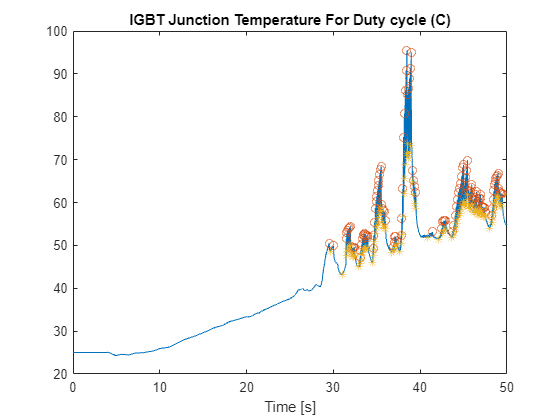

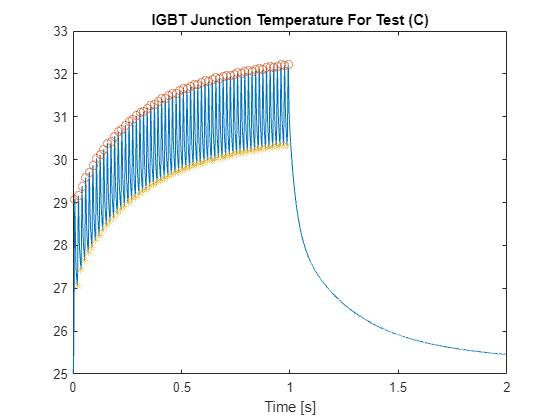

% Script For inverter life estimation
PeakItest = 67.5; %Peak 
EOLrTh = 0.2 ; % end of life thermal resistance (Rth)
TestEqCycles = PMSMcountEqTest(PeakItest);

InverterLife = PMSMgetDutyLife(PeakItest,EOLrTh,TestEqCycles)

InverterLife = 1.3356e+06

dutyCycle = "US06";% Name of the standard test duty cycle 

   To regenerate the time series junction temperature data for a different duty or test cycle, run sample script in the command prompt. 